%%Try different fitting mothed by fitting to the simulatted polarized gas
%define all the physical constant here:
mli=9.988346*10^-27;  %kg
hbar=1.0545718*10^(-34); %SI
hh=2*pi*hbar;%SI Planck constant
omega=23.9*2*pi; %in rad/s
pixellength=1.44*10^-6; %in m
sigma0=0.215*10^-12/2; %in m^2
Nsat=330; %P63I Camera
warning('off','all');
[ KappaTildeT, PTildeT, Z_vecT ] = IdealFermiEOS( 1.1,30, 5000 );

% %First try to Check P/P0 vs Z and kappa/kappa_0 at T/TF=0.1
% load('polarized_simulated_T0_1_noise_hires.mat');
% 
% scatter(y_vec,n_simulated)
% % scatter(y_vec,PTilde)
% Z=y_vec;
% 
% n=n_simulated_noise(Z>=0);
% PTilde=PTilde(Z>=0);
% KappaTilde=KappaTilde(Z>=0);
% Z=Z(Z>=0);
% V=0.5*mli*omega^2*Z.^2;
% 
% [Vsort,B]=sort(V);
% nsort=n(B);
% Zsort=Z(B);
% PTildesort=PTilde(B);
% KappaTildesort=KappaTilde(B);
% [~,~,Pt]=GetPvsV(nsort,Vsort);
% Kt=GetKappavsV(nsort,Vsort);


% %Plot the image for last section
% figure1 = figure('Name','Figure');
% axes1 = axes('Parent',figure1);
% hold(axes1,'on');
% plot1=plot(Zsort,Pt,'r.');
% plot2=plot(Zsort,PTildesort);
% set(plot1,'DisplayName','Get P/P_0 from simulated data','Marker','.',...
%     'LineStyle','none',...
%     'Color',[1 0 0]);
% set(plot2,'DisplayName','Theoratical');
% ylim([0,20]);xlim([0,0.4e-4])
% xlabel('Z(m)');ylabel('P/P_0');
% legend(axes1,'show');
% hold(axes1,'off')
% title('P/P_0 vs Z');
% 
% figure2=figure('Name','Figure');
% axes2=axes('Parent',figure2);
% hold(axes2,'on');
% plot1=plot(Zsort,Kt,'r.');
% plot2=plot(Zsort,KappaTildesort);
% set(plot1,'DisplayName','get \kappa/\kappa_0 from simulated data');
% set(plot2,'DisplayName','Theoratical');
% ylim([0,1]);xlim([0,0.4e-4]);
% legend(axes2,'show');
% hold(axes2,'off');
% title('\kappa/\kappa_0 vs Z');
% 
% p1=plot(PTildesort,KappaTildesort,'g.');
% hold on
% xlim([0,5]);ylim([0,1])
% p2=plot(PTildeT,KappaTildeT);
% p3=scatter(Pt,Kt);
% set(p1,'DisplayName','EoS in Dataset');
% set(p2,'DisplayName','EoS Theoratical');
% set(p3,'DisplayName','EoS Calculated');
% legend('show');
% title('Consistency check');
% hold off

% %%First try to figure out what's causing the double tail issue.
% %try discard half of the data set
% load('polarized_simulated_T0_5_noise_hires.mat');
% 
% % scatter(y_vec,n_simulated)
% % scatter(y_vec,PTilde)
% Z=y_vec;
% 
% n=n_simulated(Z>=0);
% PTilde=PTilde(Z>=0);
% KappaTilde=KappaTilde(Z>=0);
% Z=Z(Z>=0);
% V=0.5*mli*omega^2*Z.^2;
% 
% [Vsort,B]=sort(V);
% nsort=n(B);
% Zsort=Z(B);
% PTildesort=PTilde(B);
% KappaTildesort=KappaTilde(B);
% [~,~,Pt]=GetPvsV(nsort,Vsort);
% Kt=GetKappavsV(nsort,Vsort);
% 

% %%Plot the image for last section
% figure1 = figure('Name','Figure');
% axes1 = axes('Parent',figure1);
% hold(axes1,'on');
% plot1=plot(Zsort,Pt,'r.');
% plot2=plot(Zsort,PTildesort);
% set(plot1,'DisplayName','Get P/P_0 from simulated data','Marker','.',...
%     'LineStyle','none',...
%     'Color',[1 0 0]);
% set(plot2,'DisplayName','Theoratical');
% ylim([0,60]);xlim([0,0.6e-4])
% xlabel('Z(m)');ylabel('P/P_0');
% legend(axes1,'show');
% hold(axes1,'off')
% title('P/P_0 vs Z');
% 
% figure2=figure('Name','Figure');
% axes2=axes('Parent',figure2);
% hold(axes2,'on');
% plot1=plot(Zsort,Kt,'r.');
% plot2=plot(Zsort,KappaTildesort);
% set(plot1,'DisplayName','get \kappa/\kappa_0 from simulated data');
% set(plot2,'DisplayName','Theoratical');
% ylim([0,1]);xlim([0,0.6e-4]);
% legend(axes2,'show');
% hold(axes2,'off');
% title('\kappa/\kappa_0 vs Z');
% 
% p1=plot(PTildesort,KappaTildesort,'g.');
% hold on
% xlim([0,30]);ylim([0,1])
% p2=plot(PTildeT,KappaTildeT);
% p3=scatter(Pt,Kt);
% set(p1,'DisplayName','EoS in Dataset');
% set(p2,'DisplayName','EoS Theoratical');
% set(p3,'DisplayName','EoS Calculated');
% legend('show');
% title('Consistency check');
% hold off

N=length(n_simulated_noise_list);
Ptlist=[];
Ktlist=[];
Zlist=[];
for i=1:N
    Z=y_vec';
    n=n_simulated_noise_list{i}';
    n=n(Z>=0);
    Z=Z(Z>=0);
    V=0.5*mli*omega^2*Z.^2;
    [Vsort,B]=sort(V);
    nsort=n(B);
    Zsort=Z(B);
    
    [~,~,Pt]=GetPvsV(nsort,Vsort);
    Kt=GetKappavsV(nsort,Vsort);
    
    Pt(Z>3.5e-5)=[];Kt(Z>3.5e-5)=[];
    Pt(Z<.35e-5)=[];Kt(Z<.35e-5)=[];
    Ptlist=[Ptlist;Pt];Ktlist=[Ktlist;Kt];
end


PtBinMin=0;
PtBinMax=30;
dPt=0.2;
Ptbin=PtBinMin:dPt:PtBinMax;
Nbin=size(Ptbin,2);
M=length(Ktlist);
KtBinList=cell(1,Nbin);
KtMean=zeros(1,Nbin);
KtStd=zeros(1,Nbin);
for i=1:Nbin
    KtBinList{i}=[];
end

for i=1:M
    K=round((Ptlist(i)-PtBinMin)/dPt+1);
    if K<=Nbin && K>=1
        temp=KtBinList{K};
        KtBinList{K}=[temp,Ktlist(i)];
    end
end

for i=1:Nbin
    KtMean(i)=mean(KtBinList{i});
    KtStd(i)=std(KtBinList{i});
end

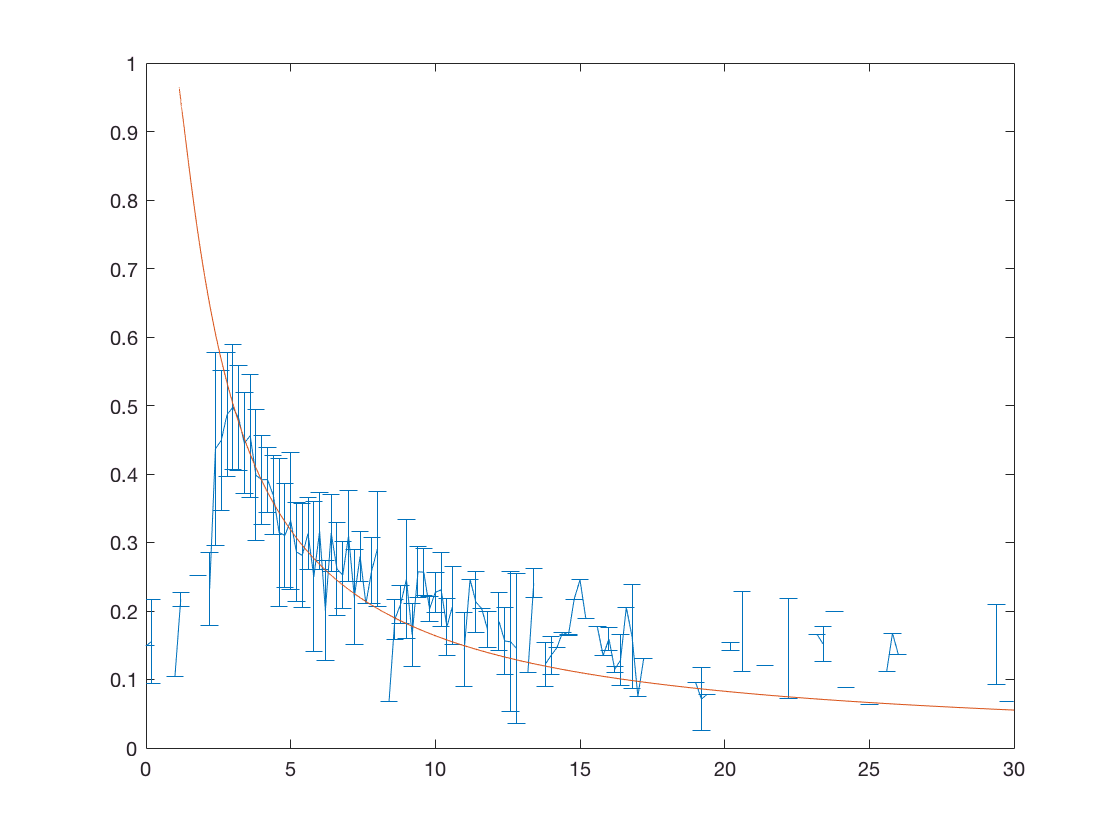

figure
errorbar(Ptbin,KtMean,KtStd);
hold on
plot(PTildeT,KappaTildeT)
hold off
xlim([0,30]);ylim([0,1]);